In this .mlx file, the sounds of three animals (elephant, sheep and owl) will be analyzed. 

The main points of interest are their frequency-range, as well as their dominant frequency.

## Reading the .wav files with audioread.

% double will be used for compatibility
[e, fs_e] = audioread('elephant.wav', 'double');
[o, fs_o] = audioread('owl.wav', 'double');
[s, fs_s] = audioread("sheep.wav", 'double');

% because memory efficiency
if fs_e == fs_s && fs_s == fs_o
    fs = fs_e; 
    clearvars fs_e fs_o fs_s;
end


## Doing analytics with periodogram() and pwelch().

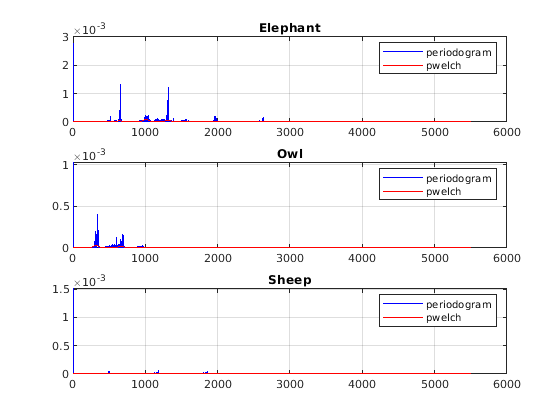

[Pxxe_p, Fe0_p] = periodogram(e, hann(length(e)), length(e),fs);
[Pxxo_p, Fo0_p] = periodogram(o, hann(length(o)), length(o),fs);
[Pxxs_p, Fs0_p] = periodogram(s, hann(length(s)), length(s),fs);

window = hann(256);
noverlap = 128;
nfft = 256;

[Pxxe_w, Fe0_w] = pwelch(e, window, noverlap, nfft,fs);
[Pxxo_w, Fo0_w] = pwelch(o, window, noverlap, nfft,fs);
[Pxxs_w, Fs0_w] = pwelch(s, window, noverlap, nfft,fs);

figure(1)
subplot(3,1,1)
plot(Fe0_p, Pxxe_p, 'b');
hold on
plot(Fe0_w, Pxxe_w, 'r');
title("Elephant")
legend('periodogram', 'pwelch')
grid on

subplot(3,1,2)
plot(Fo0_p, Pxxo_p, 'b');
hold on
plot(Fo0_w, Pxxo_w, 'r');
title("Owl")
legend('periodogram', 'pwelch')
grid on

subplot(3,1,3)
plot(Fs0_p, Pxxs_p, 'b');
hold on
plot(Fs0_w, Pxxs_w, 'r');
title("Sheep")
legend('periodogram', 'pwelch')
grid on

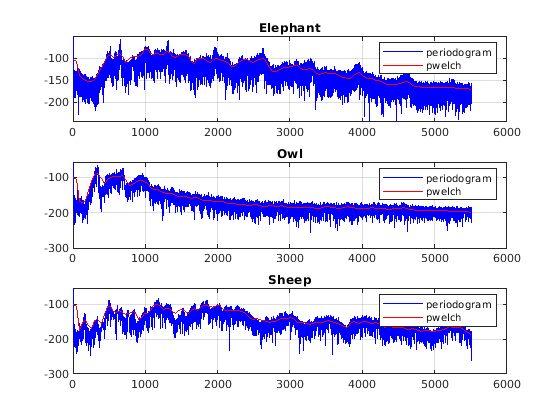


figure(2)
subplot(3,1,1)
plot(Fe0_p, mag2db(Pxxe_p), 'b');
hold on
plot(Fe0_w, mag2db(Pxxe_w), 'r');
title("Elephant")
legend('periodogram', 'pwelch')
grid on

subplot(3,1,2)
plot(Fo0_p, mag2db(Pxxo_p), 'b');
hold on
plot(Fo0_w, mag2db(Pxxo_w), 'r');
title("Owl")
legend('periodogram', 'pwelch')
grid on

subplot(3,1,3)
plot(Fs0_p, mag2db(Pxxs_p), 'b');
hold on
plot(Fs0_w, mag2db(Pxxs_w), 'r');
title("Sheep")
legend('periodogram', 'pwelch')
grid on

After this first series of tests the results are the following:

- The frequency range of the elephant is 460Hz - 2700 Hz

- The frequency range of the owl is 250Hz - 1050 Hz

- There are no conclusions to be drawn from the graph of the sheep.

- Every spectrum has some kind of anomaly at 0 Hz;

- All of the graphs are a bit hard to read, even when plotted with dB.

Let's try analyzing them with parametric estimation methods.

## Analysis with pburg().

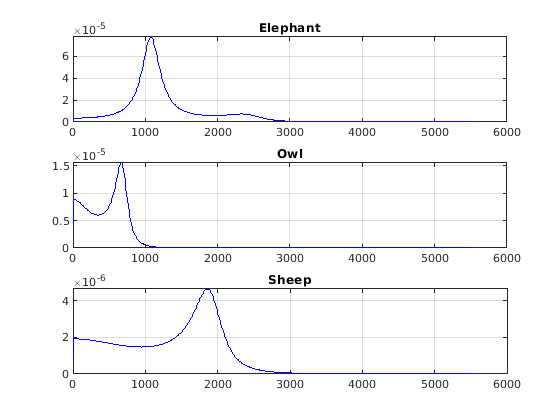


order = 4;
nfft = 1024;

[Pxxe1, Fe1] = pburg(e, order, nfft, fs);
[Pxxo1, Fo1] = pburg(o, order, nfft, fs);
[Pxxs1, Fs1] = pburg(s, order, nfft, fs);

figure(3)
subplot(3,1,1)
plot(Fe1, Pxxe1, 'b');
title("Elephant")
grid on

subplot(3,1,2)
plot(Fo1, Pxxo1, 'b');
title("Owl")
grid on

subplot(3,1,3)
plot(Fs1, Pxxs1, 'b');
title("Sheep")
grid on

These graphs are much easier to draw a conclusion from.  The frequency ranges that have been determined from the previous analytic procedures are about right. The sheep's frerquency range is around 0 - 2300 Hz.

Now let us find the dominant frequency of the signals.

## Dominant frequency.

[dfE_amplitude, dfE_index] = max(Pxxe1);
[dfO_amplitude, dfO_index] = max(Pxxo1);
[dfS_amplitude, dfS_index] = max(Pxxs1);

dfreq_e = Fe1(dfE_index, 1);
dfreq_o = Fo1(dfO_index, 1);
dfreq_s = Fs1(dfS_index, 1);

disp("The dominant frequencies are:")

The dominant frequencies are:


disp("Elephant: " + dfreq_e);

Elephant: 1076.6602


disp("Owl: " + dfreq_o);

Owl: 667.5293


disp("Sheep: " + dfreq_s);

Sheep: 1851.8555
